%https://uk.mathworks.com/matlabcentral/fileexchange/74545-generalized-seir-epidemic-model-fitting-and-computation?s_tid=LandingPageTabfx
%https://github.com/ECheynet/SEIR
%https://github.com/CSSEGISandData/COVID-19


status = {'confirmed','deaths','recovered'};

url = ['https://github.com/CSSEGISandData/COVID-19/blob/master/csse_covid_19_data/csse_covid_19_time_series/time_series_covid19_',status{1},'_global.csv'];

outfilename = websave(filename,url)

Use the readtable function to load the data set covid.csv

Plot China (Hubei) and UK

Using logarithmic plots

Select the different provinces from China and compare the number of evolution of the number of confirmed cases for the different regions

Select different regions for Europe (France, Spain Germany, UK ) and compare the time evolution for the number of compared cases

Use the websave command to download the data from

note

status = {'Confirmed','Deaths','Recovered'};

     url = ['https://raw.githubusercontent.com/CSSEGISandData/COVID-19/master/csse_covid_19_data/csse_covid_19_time_series/time_series_19-covid-',status{ii},'.csv'];

use filename="myout.csv" to store the read data

outfilename = websave(filename,url)

https://github.com/CSSEGISandData/COVID-19/blob/master/csse_covid_19_data/csse_covid_19_time_series/time_series_covid19_confirmed_global.csv

data=readtable('../data/mtcars.csv')

pdhp =   NormalDistribution

  Normal distribution
       mu = 146.688   [121.968, 171.407]
    sigma = 68.5629   [54.9671, 91.1529]


Plot a 2x2 subplot array illustrating the relationship between mpg and the properties cyl, disp, wt and hp

experiment with mean median and mode which variables exhibit the greatest difference between these values


histogram(data.hp)
histogram(data.wt)


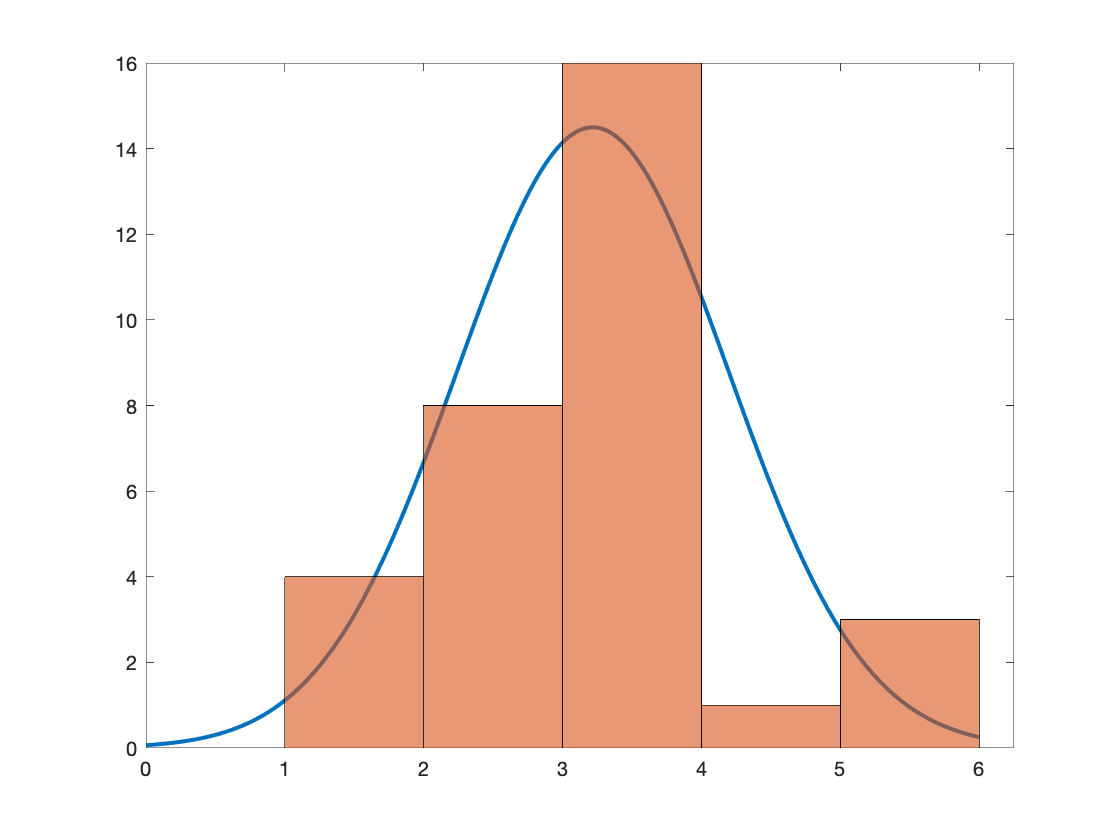

pdhp = fitdist(data.hp,'Normal')
x_values = 0:0.01:6;

pdwt =   NormalDistribution

  Normal distribution
       mu =  3.21725   [2.86448, 3.57002]
    sigma = 0.978457   [0.784433, 1.30084]


y = 16*pdf(pdwt,x_values)/0.45;
plot(x_values,y,'LineWidth',2)
hold on
histogram(data.wt)

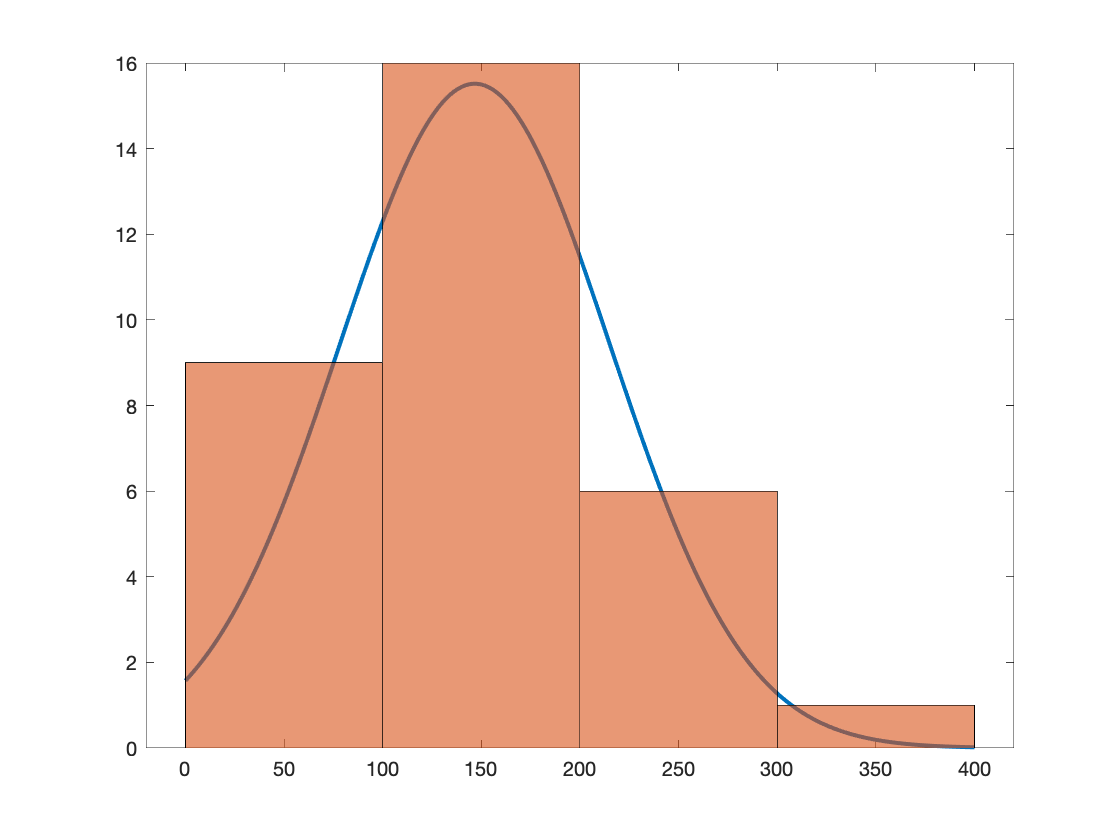

hold off

pdwt = fitdist(data.wt,'Normal')

x_values = 0:2:400;

y = 16000*pdf(pdhp,x_values)/6;

xv =   160.0000
  160.0000
  108.0000
  258.0000
  360.0000
  225.0000
  360.0000
  146.7000
  140.8000
  167.6000


plot(x_values,y,'LineWidth',2)

yv =    21.0000
   21.0000
   22.8000
   21.4000
   18.7000
   18.1000
   14.3000
   24.4000
   22.8000
   19.2000


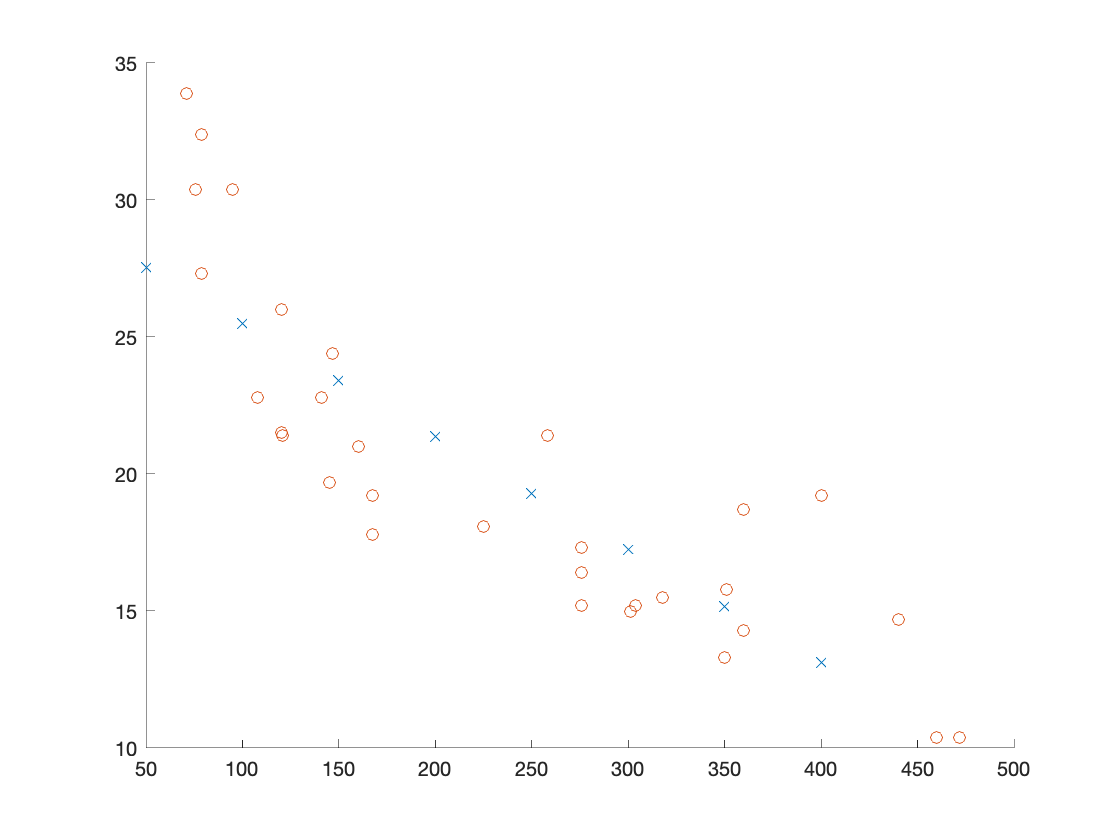

hold on
histogram(data.hp)

hold off

Use the least squareas method   to compute the best fit

Least squares method

[http://mathworld.wolfram.com/LeastSquaresFitting.html](http://mathworld.wolfram.com/LeastSquaresFitting.html)

xv=data.disp
yv=data.mpg